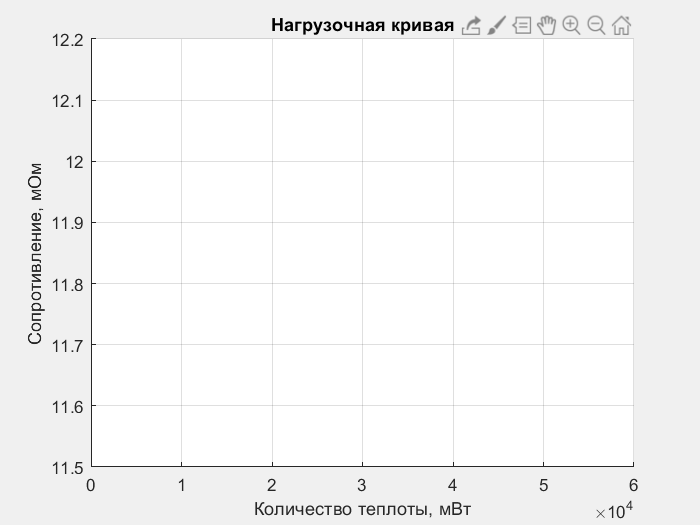

R_atm =    11.5498
   11.5746
   11.6484
   11.7252
   11.8444
   11.9666
   12.1318


Q_atm = 	1.0e+04 *

    0.1295
    0.4406
    1.1288
    1.8807
    3.0362
    4.1740
    5.8296


% Импортируйте данные из csv-файлов
spectra = importdata("spectra.csv");
starNames = importdata("star_names.csv");
lambdaStart = importdata("lambda_start.csv");
lambdaDelta = importdata("lambda_delta.csv");
% Определите константы
lambdaPr = 656.28; %нм
speedOfLight = 299792.458; %км/c
the_amount_of_stars = size(starNames, 1);
the_amount_of_observations = size(spectra, 1);
% Определите диапазон длин волн
lambdaEnd = lambdaStart + (the_amount_of_observations - 1) * lambdaDelta;
lambda = (lambdaStart:lambdaDelta:lambdaEnd)';
% Рассчитайте скорости звезд относительно Земли
min_intensities = min(spectra);
min_lambdas = rand(1, the_amount_of_stars);
min_indexes = rand(1, the_amount_of_stars);
speed = rand(the_amount_of_stars, 1);
for number = 1:the_amount_of_stars
    [a, idx] = min(spectra(:, number));
    min_indexes(1, number) = idx;
    min_lambdas(1, number) = lambda(idx, 1);
end
for number = 1:the_amount_of_stars
    speed(number) = speedOfLight * ((min_lambdas(1, number) / lambdaPr) - 1);
end
movaway = starNames(speed > 0)
% Постройте график
fg1=figure
set(fg1, 'Visible', 'on')
hold on
for number = 1:the_amount_of_stars
    if (speed(number) > 0)
        plot(lambda, spectra(:, number), "-", 'LineWidth', 3)
    end
    if (speed(number) < 0)
        plot(lambda, spectra(:, number), "--", 'LineWidth', 1)
    end
end
legend(starNames)
grid on
xlabel('Длина волны, нм')
ylabel(['Интенсивность, эрг/см^2/с/', char(197)])
title({'Спектры звёзд', 'в созвездии Льва'})
hold off
% Сохраните график
saveas(fg1, 'спектры.png')